# 固有値・固有ベクトルが複素数の場合

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all;
sympref('MatrixWithSquareBrackets',true);
syms theta lambda
A=[[cos(theta);sin(theta)],[-sin(theta);cos(theta)]]

$$A = \left[\begin{array}{cc} \cos\left(\theta \right) & -\sin\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right]$$

simplify(det(lambda*eye(2)-A))==0

$$ans = \lambda^{2}-2\,\cos\left(\theta \right)\,\lambda +1=0$$

simplify(solve(ans,lambda))

$$ans = \left[\begin{array}{c} \cos\left(\theta \right)+\sqrt{{\cos\left(\theta \right)}^{2}-1}\\ \cos\left(\theta \right)-\sqrt{{\cos\left(\theta \right)}^{2}-1} \end{array}\right]$$

det(A)

$$ans = {\cos\left(\theta \right)}^{2}+{\sin\left(\theta \right)}^{2}$$

simplify(det(A))

$$ans = 1$$

thetaを残したまま固有値と固有ベクトルを求める．複素数が含まれる．

[V,D]=eig(A)

$$V = \left[\begin{array}{cc} \frac{\cos\left(\theta \right)-1\,\sin\left(\theta \right)\,\mathrm{i}}{\sin\left(\theta \right)}-\frac{\cos\left(\theta \right)}{\sin\left(\theta \right)} & \frac{\cos\left(\theta \right)+1\,\sin\left(\theta \right)\,\mathrm{i}}{\sin\left(\theta \right)}-\frac{\cos\left(\theta \right)}{\sin\left(\theta \right)}\\ 1 & 1 \end{array}\right]$$

$$D = \left[\begin{array}{cc} \cos\left(\theta \right)-1\,\sin\left(\theta \right)\,\mathrm{i} & 0\\ 0 & \cos\left(\theta \right)+1\,\sin\left(\theta \right)\,\mathrm{i} \end{array}\right]$$

theta=pi/6を代入して固有値と固有ベクトルを求める．

[V,D]=eig(subs(A,theta,pi/6))

$$V = \left[\begin{array}{cc} -1\,\mathrm{i} & 1\,\mathrm{i}\\ 1 & 1 \end{array}\right]$$

$$D = \left[\begin{array}{cc} 0.8660-0.5000\,\mathrm{i} & 0\\ 0 & 0.8660+0.5000\,\mathrm{i} \end{array}\right]$$

figure
hold on;
grid on;axis equal;
set(gca,'fontname','メイリオ','fontsize',14);
quiver(0, 0, 1, 0, 'b-','LineWidth',1,'AutoScale','off');
quiver(0, 0, 0, 1, 'b-','LineWidth',1,'AutoScale','off');
text(1,0,'$e_1$','Interpreter','latex','FontSize',14)
text(0,1,'$e_2$','Interpreter','latex','FontSize',14)
text(0.25,0.8, ['$A=' latex(A) '$'],'Interpreter','latex','FontSize',14)
text(0.175*cos(pi/12),0.175*sin(pi/12),'$\theta$','Interpreter','latex','FontSize',14)
plot(0.15*cos(linspace(0,pi/6,20)),0.15*sin(linspace(0,pi/6,20)),'k-')
A=subs(A,theta,pi/6)

$$A = \left[\begin{array}{cc} 0.8660 & -0.5000\\ 0.5000 & 0.8660 \end{array}\right]$$

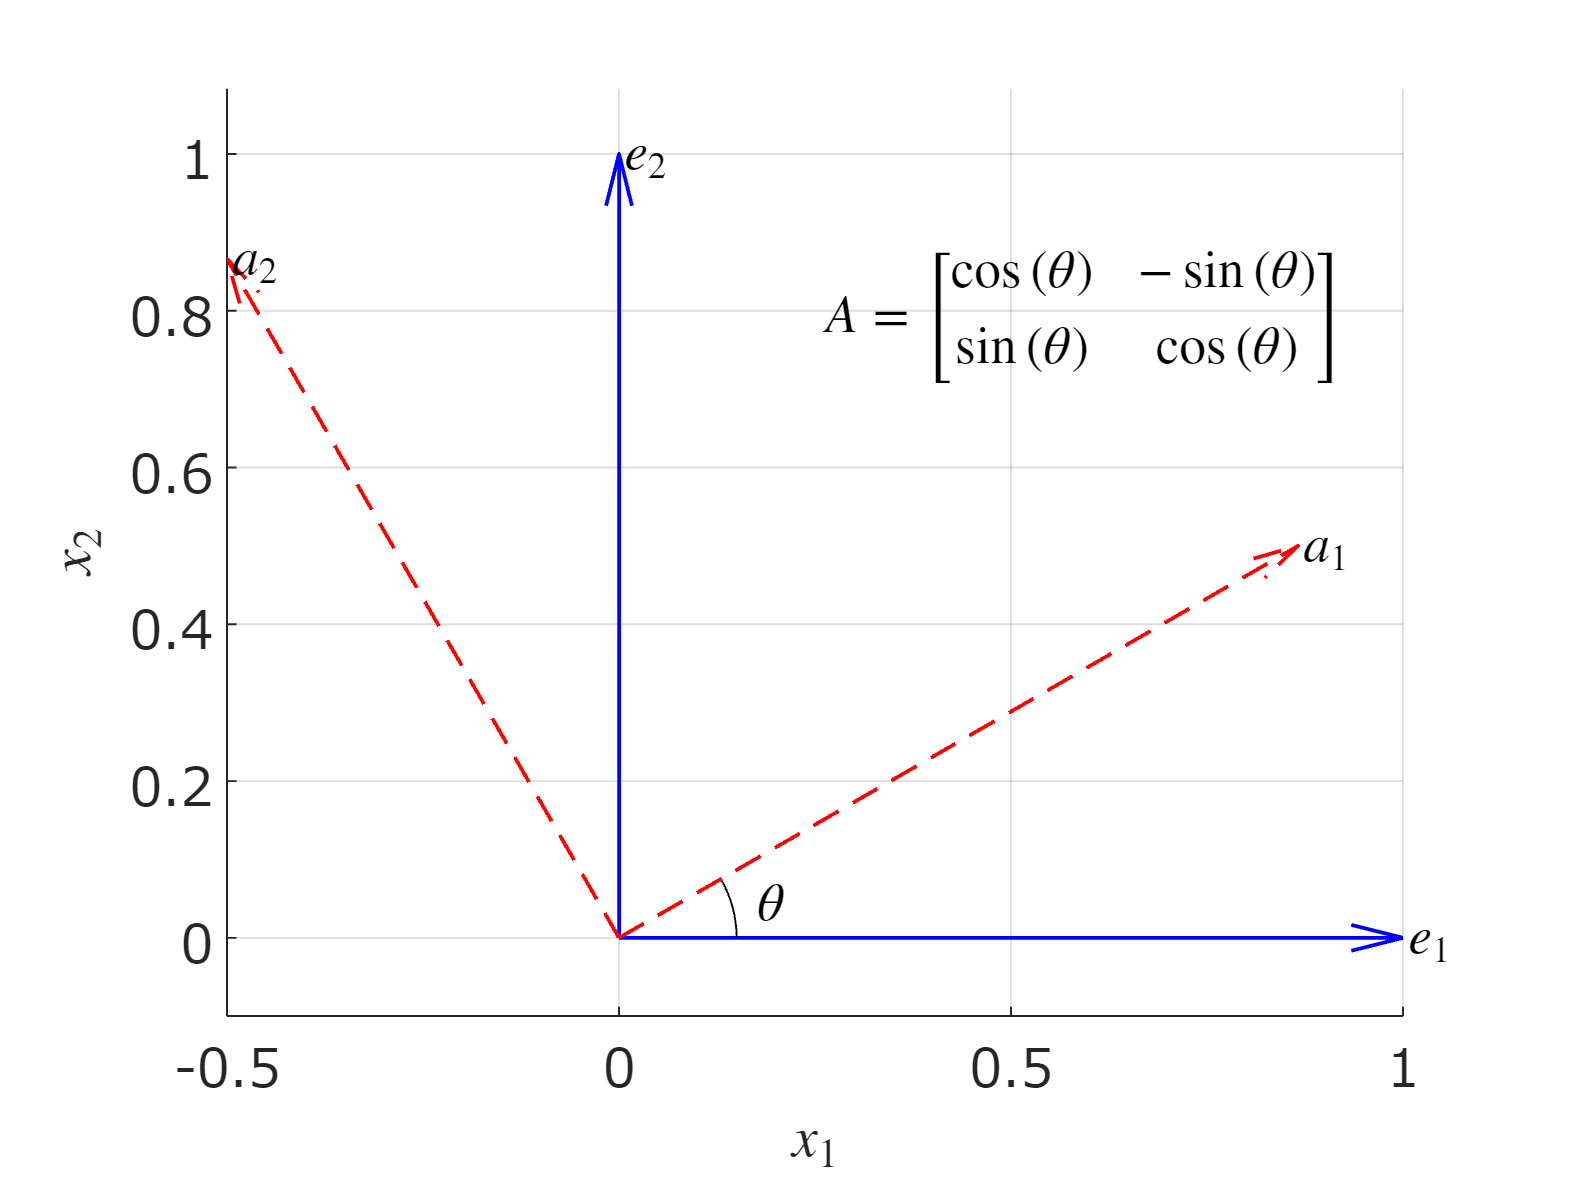

quiver(0, 0, A(1,1), A(2,1), 'r--','LineWidth',1,'AutoScale','off');
quiver(0, 0, A(1,2), A(2,2), 'r--','LineWidth',1,'AutoScale','off');
text(A(1,1),A(2,1),'$a_1$','Interpreter','latex','FontSize',14)
text(A(1,2),A(2,2),'$a_2$','Interpreter','latex','FontSize',14)
xlabel('$x_1$','Interpreter','latex');ylabel('$x_2$','Interpreter','latex');
exportgraphics(gcf,'fig_eigValVecSample_rot.pdf')